# **Olin Oval Robot Rover**

**OvalRoverSimulation.mlx is a simulation of a planetary rover**

This code simulates a wheeled autonomous planetary rover performing multiple missions on the Olin Oval

- It takes desired location waypoints as inputs

- It delivers a moving map simulation of rover transversing the Oval as an output

Written by Gabrielle Blake. 1 February 2021. Revision A.

clc;                                % clear command window
clear;                              % clear MATLAB workspace

## **Set up robot control system **( code that runs once )

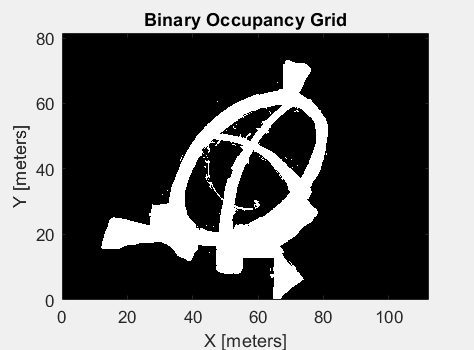

img = imread('OlinOvalMap.png');                    % load oval image (from Canvas)
grayimage = im2gray(img);                           % convert to grayscale
bwimage = grayimage < 0.5;                          % convert to black and white
MapOfOval = binaryOccupancyMap(bwimage, 10);        % convert to a binary occupancy map in meters
show(MapOfOval);                                    % show map

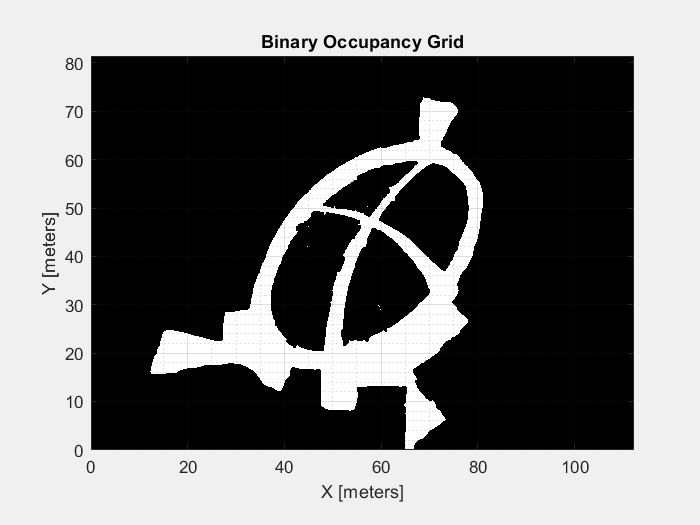

% Inflate the map with the robot rover size, so robot can be treated as a point. Assume
% robot rover is 0.25m long, bow to stern.
MapOfOvalInflated = copy(MapOfOval);                % make a copy, don't lose original data
inflate(MapOfOvalInflated, 0.25);                   % dilate map to accommodate robot body size

% livescript does some funky stuff whan you try to update in line plots quickly, so create a free
% floating figure for map to deal with livescript update problem
ovalTrack = figure('name', 'OvalTrackMap', 'NumberTitle', 'off', 'Visible', 'on');
figure(ovalTrack)                                   % got to ovalTrack figure for next plot
        show(MapOfOvalInflated);                    % show new map in a new figure window
        grid on;
        grid minor;

Create a lidar based map of the world ( to be filed in as Rover drives around oval 

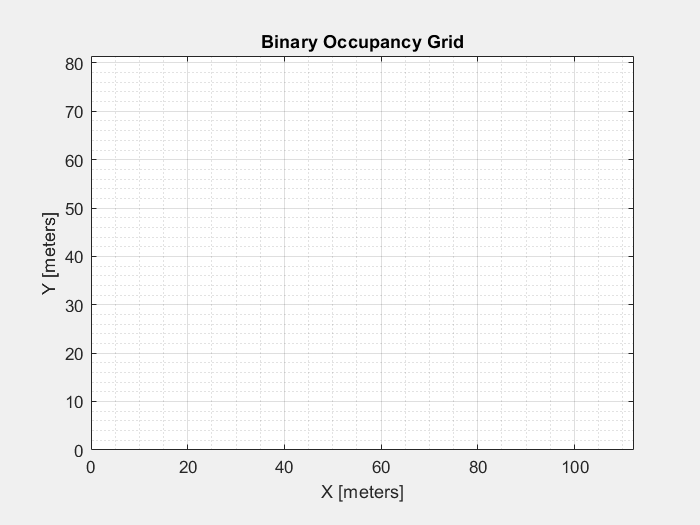

% Create an empty map of the same dimensions as the test track map
[mapdimx, mapdimy] = size(bwimage);                             % find size of map image
lidarMap = binaryOccupancyMap(mapdimx, mapdimy, 10, "grid");    % make empty map the same size

% create a free floating figure for map to deal with livescript update problem
roverLidarScan = figure('name', 'RoverLidarScan', 'NumberTitle', 'off', 'Visible', 'on');
        show(lidarMap);
        grid on;
        grid minor;

% yes it should start out blank, it will get filled as the rover drives and collects data

Create a differential drive robot rover ( this model takes robot vehicle speed and heading for inputs )

diffDriveRover = differentialDriveKinematics("VehicleInputs", "VehicleSpeedHeadingRate");

Create a pure pursuit rover controller ( this controller generates the robots speed and heading needed to follow a desired path, set desired linear velocity and max angular velocity in m/s and rad/s )

RoverController = controllerPurePursuit("DesiredLinearVelocity", 2, "MaxAngularVelocity", 3);

Create 360 degree LIDAR range sensor for your rover.

- Create a sensor with max range of 40 meters. This sensor simulates

- range readings based on a given pose and map. The Olin Oval map is used

- with this range sensor to simulate collecting sensor readings in an unknown environment

- Its a litle hard to find documentation on **rangeSensor** function, so right click on it and choose "help or f1

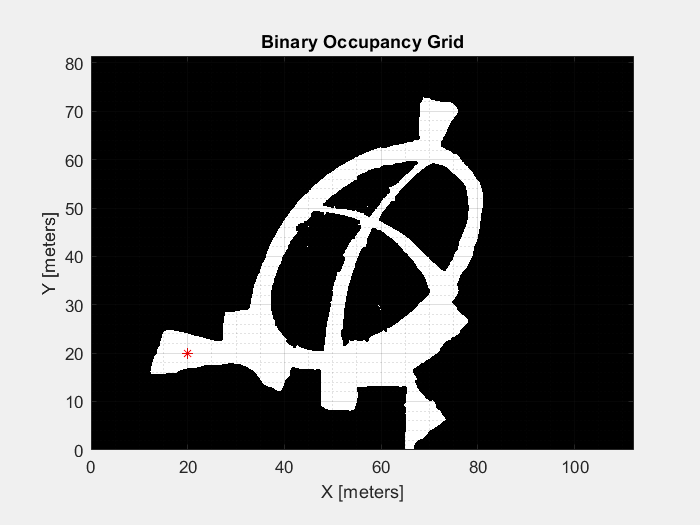

lidar = rangeSensor;                                % creates a rangeSensor system object see help for info
lidar.Range = [0.5, 40];                            % sets minimum and maximum range of sensor
testPose = [20 20 pi/2];                            % sets an initial pose for lidar

% Plot the test spot for lidar scan on the reference Olin Oval Map
figure(ovalTrack);                                  % designate free floating OvalTrackMap to draw on
hold on;
plot(20, 20, 'r*');                                 % plot robot position in oval
hold off;

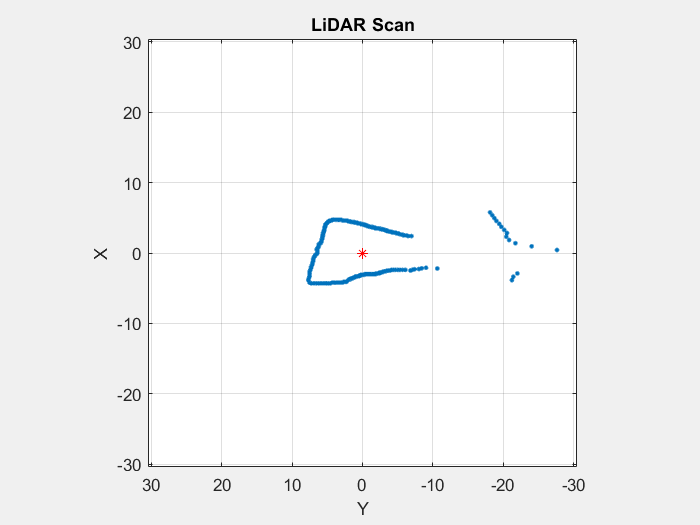

% Generate a lidar test scan from test position
    [ranges, angles] = lidar(testPose, MapOfOvalInflated);
    scan = lidarScan(ranges, angles);

%Visualize the test lidar scan data in robot coordinate system.
% Create a new free-standing figure to display the local lidar data, rover
% at center
    localLidarPlot = figure('Name', 'locallidarMap', 'NumberTitle', 'off', 'Visible', 'on');
    figure(localLidarPlot)
    plot(scan)
    hold on;
    plot(0, 0, 'r*');                               % plot robot position
    hold off;

Create a test path to drive through the map for gathering range sensor readings.

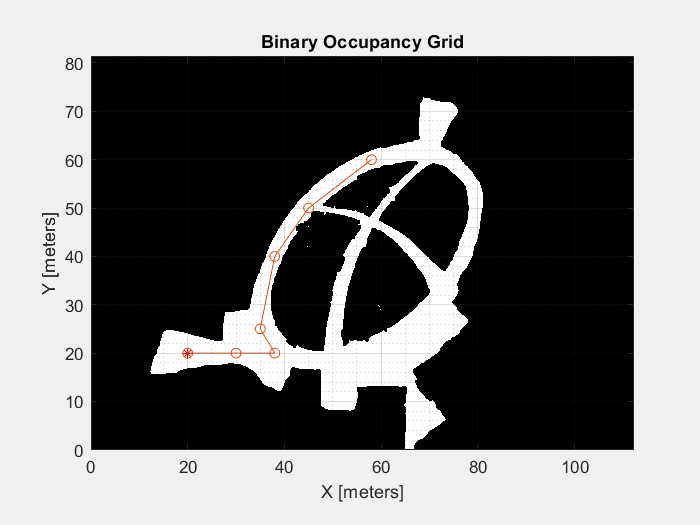

path = [20 20; 30 20; 38 20; 35 25; 38 40; 45 50; 58 60];   % path waypoints

% Plot the path on the reference map figure.
figure(ovalTrack)                                           % select OvalTrackMap
hold on
plot(path(:, 1), path(:, 2), 'o-');                         % plot path on it
hold off

Use this test path as the set of waypoints the pure pursuit controller will follow:

RoverController.Waypoints = path;                           % set rover waypoints

Set the initial pose and final goalWayPoint location based on the path. Create global variables for storing the current pose and an index for tracing the iterations.

initRoverPose = [path(1,1) path(1,2), pi/2];                % store initial location and orientation of rover
goalWayPoint = [path(end,1) path(end,2)]';                  % path end waypoint
sampleTime = 0.10;                                          % Sample time [s]
t = 0:sampleTime:100;                                       % Time array
robotPoses = zeros(3, numel(t));                            % Pose matrix
robotPoses(:,1) = initRoverPose';                           % store robot robotPoses
r = rateControl(1/sampleTime);                              % reset control loop rate
reset(r);                                                   % reset loop time to zero


Ready to run robot, ask operator if they are set and suggest they move plots to a visable position.

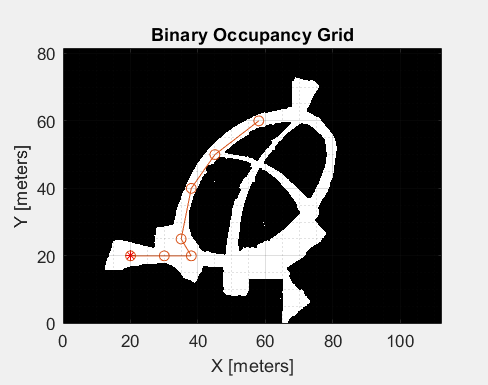

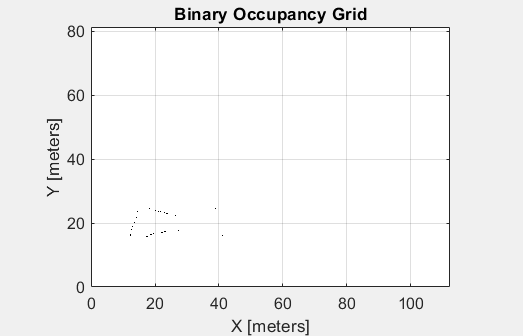

runRover = input("Ready to run Rover? Please arrange your data plot figures for clear visibility, then enter 1 or 0 and hit enter.");

clc

## **Run robot control loop **( code that runs over and over )

Load a map

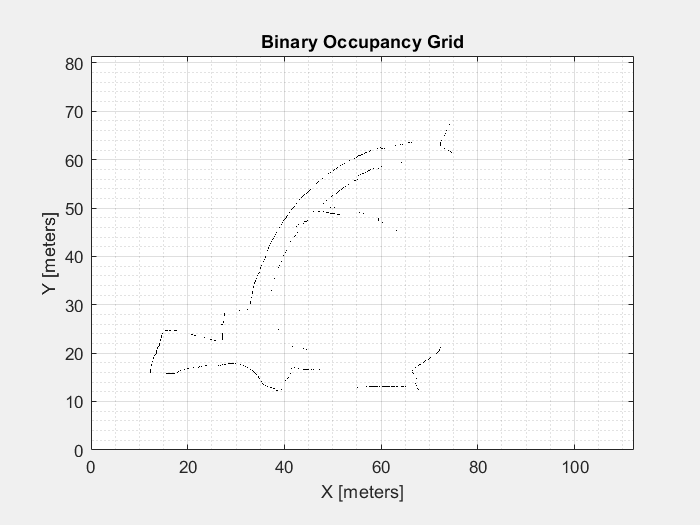

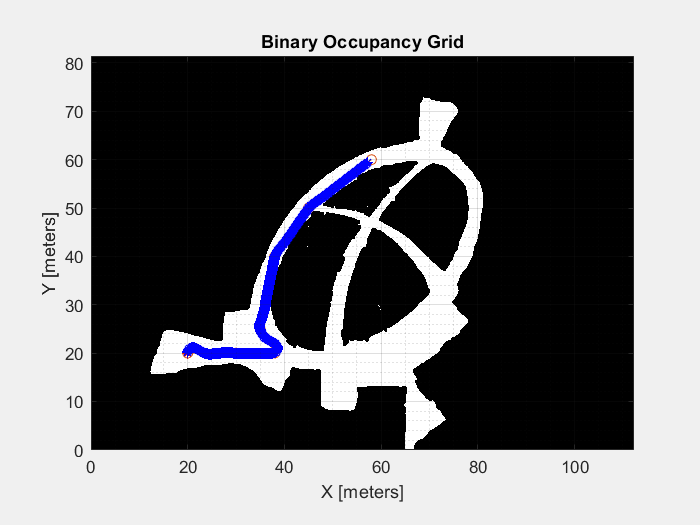

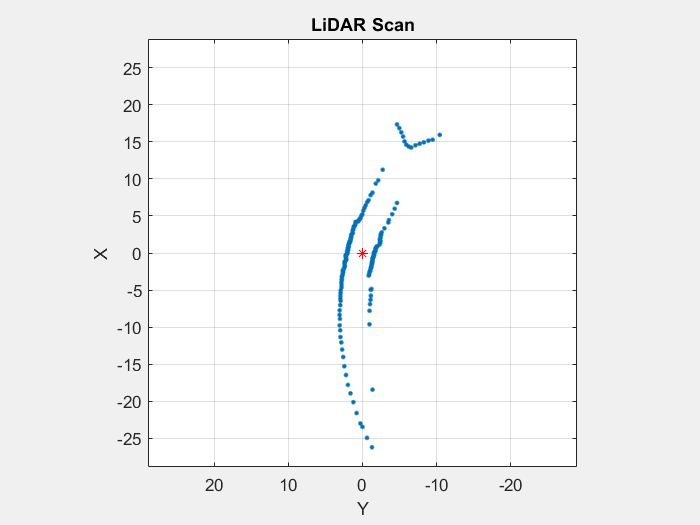

Goal position reached


controlIndex = 1;                               % create a robot loop control
while (controlIndex < numel(t))                 % loop for number of elements in t
    position = robotPoses(:, controlIndex)';    % rover's current position
    roverLocation = position(1:2);              % current rover X and Y from position

    % End loop if rover has reached goal waypoint within tolerance of 1.0m
        dist = norm(goalWayPoint'-roverLocation);
        if (dist < 1.0)                         % robot reaches end goal
            disp("Goal position reached")
            break;                              % stop control loop       
        end

    % SENSE: collect data from robot lidar
    % function [ranges, angles] = SENSE(position, mapOfTrack,
    % blankLidarMap, fig_lidarMap, figlocalLidarPlot, lidar)
    [ranges, angles] = SENSE(position, MapOfOvalInflated, lidarMap, roverLidarScan, localLidarPlot, lidar);

    % THINK: compute what robot should next
    % function [roverX, roverY, poses] = THINK(poses, diffDrive, ppControl,
    % sampleTime, loopIndex)
    [roverX, roverY, robotPoses] = THINK(robotPoses, diffDriveRover, RoverController, sampleTime, controlIndex);

    % ACT: command robot actuators
    % function ACT(roverX, roverY, fig_testTrack)
    ACT(roverX, roverY, ovalTrack);

    controlIndex = controlIndex + 1;            % increment control loop index
    waitfor(r);                                 % wait for loop cycle to complete

end

beep;                                           % give audio indication wapoint is reached

## **Robot Functions ** ( store this codes local funcion here )

In practice for modularity, readability and longevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions. Functions also well support team programming as each sub-team can develop their functions independently from the other sub-teams.

% put overall robot functions here

**Sense Functions ** ( store all Sense related local functions here )

function [ranges, angles] = SENSE(position, mapOfTrack, blankLidarMap, fig_lidarMap, fig_localLidarPlot, lidar)
% SENSE scans the reference map using the range sensor and the current
% pose.
% This simulates normal range readings for driving in an unknown
% environment.
% Update the lidar map with the range readings.
% inputs are rover position, mapOfTrack, lidarMap, figure to plot global
% lidar, figure to plot local lidar, sensor name
% outputs are lidar ranges and angles in local coordinate system

    [ranges, angles] = lidar(position, mapOfTrack);
    scan = lidarScan(ranges, angles);
    validScan = removeInvalidData(scan, 'RangeLimits', [0, lidar.Range(2)]);
    insertRay(blankLidarMap, position, validScan, lidar.Range(2));

    figure(fig_lidarMap);
        hold on;
        show(blankLidarMap);
        grid on;
        grid minor;
        hold off;

    figure(fig_localLidarPlot);
    plot(scan)
    hold on;    
    plot(0, 0, 'r*');                           % plot robot position
    hold off;

end

**Think Functions ** ( store all Think related local functions here )

function [roverX, roverY, poses] = THINK(poses, diffDrive, ppControl, sampleTime, loopIndex)
% THINK gets control commands from pure pursuit controller
% to drive to the next waypoint. Calculate derivative of robot motion
% based on control commands
% inputs are rover poses, diffDrive dynamics, loop sampleTime, loop index
% outputs are roverX, roverY, robot poses (position of robot)

        % Run the Pure Pursuit controller and
        % convert output to wheel speeds
        [vRef, wRef] = ppControl(poses(:, loopIndex));

        % Perform forward discrete integration step
        vel = derivative(diffDrive, poses(:, loopIndex), [vRef wRef]);
        poses(:, loopIndex+1) = poses(:, loopIndex) + vel * sampleTime;

        % Update rover location and pose
        roverX = poses(1, loopIndex+1);
        roverY = poses(2, loopIndex+1);

end

**Act Functions ** ( store all Act related local functions here )

function ACT(roverX, roverY, fig_testTrack)
% ACT Increment the robot pose based on the derivative
% inputs are current X and Y position of rover and fugure to plot rover in
% outputs are no outputs
        figure(fig_testTrack)
        hold on;
        plot(roverX, roverY, 'b*');         % plot robot position in oval
        hold off;

end